# Function 4:


$$f\left(z\right)=z^8 -15z^4 -16$$


The complex roots of this function are:

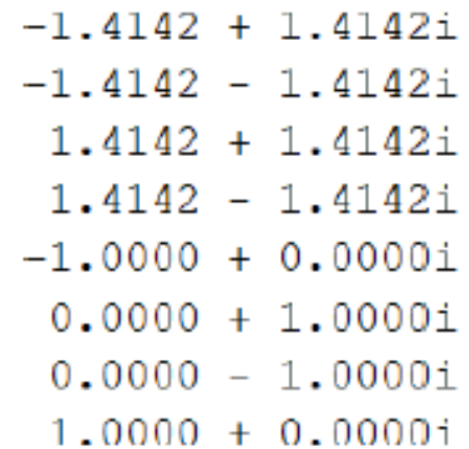

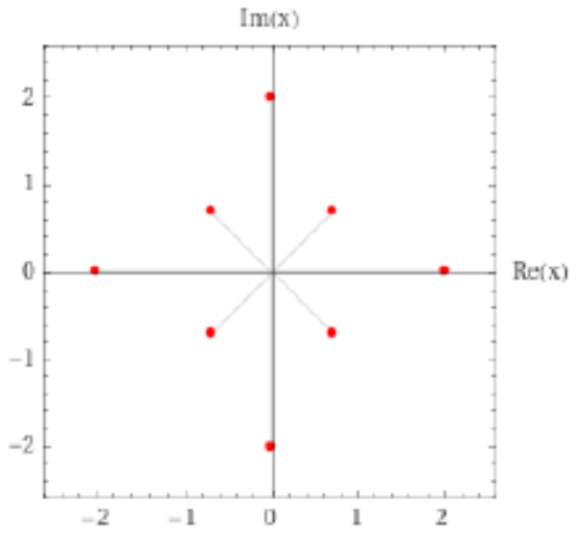

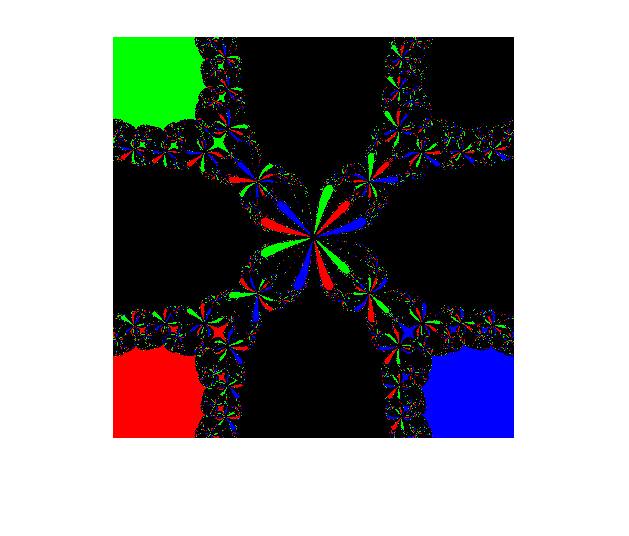

x=-2:.01:2;
x=x+eps;
y=x;
i=complex(0,1);
[X Y]=meshgrid(x,y);
Z=X+i*Y;
for j=1:64
    Z=Z-(Z.^8+15*Z.^4-16)./(8*Z.^7+60*Z.^3);
end
%coefficients in order are 1 0 0 0 15 0 0 0 -16
r=roots([1 0 0 0 15 0 0 0 -16]);
Z1=abs(Z-r(1))<=0.1;
Z2=abs(Z-r(2))<=0.1;
Z3=abs(Z-r(3))<=0.1;
a(:,:,1)=Z1*1;
a(:,:,2)=Z2*1;
a(:,:,3)=Z3*1;
figure
imshow(a)